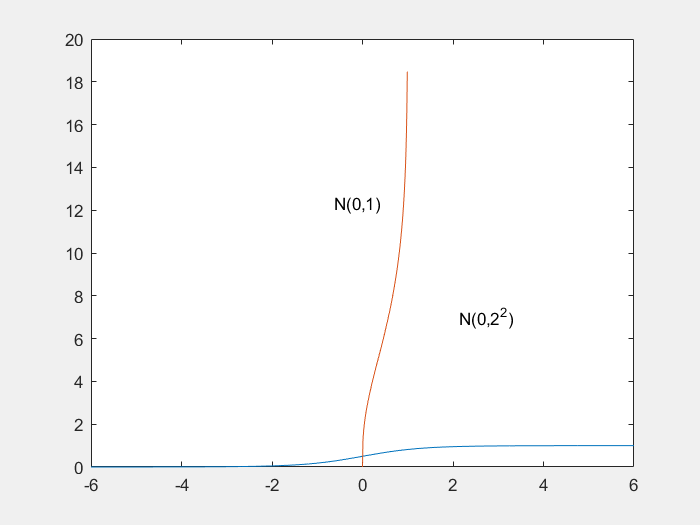

clc
clear

% 数据为一列身高 一列体重
data = [172  75  169  55  169  64  171  65  167  47 
        171  62  168  67  165  52  169  62  168  65 
        166  62  168  65  164  59  170  58  165  64 
        160  55  175  67  173  74  172  64  168  57 
        155  57  176  64  172  69  169  58  176  57 
        173  58  168  50  169  52  167  72  170  57 
        166  55  161  49  173  57  175  76  158  51 
        170  63  169  63  173  61  164  59  165  62 
        167  53  171  61  166  70  166  63  172  53 
        173  60  178  64  163  57  169  54  169  66 
        178  60  177  66  170  56  167  54  169  58 
        173  73  170  58  160  65  179  62  172  50 
        163  47  173  67  165  58  176  63  162  52 
        165  66  172  59  177  66  182  69  175  75 
        170  60  170  62  169  63  186  77  174  66 
        163  50  172  59  176  60  166  76  167  63 
        172  57  177  58  177  67  169  72  166  50 
        182  63  176  68  172  56  173  59  174  64 
        171  59  175  68  165  56  169  65  168  62 
        177  64  184  70  166  49  171  71  170  59];

% high = data(:,1:2:9);  % 取身高数据
% high = high(:);  % 转成列向量
% weight = data(:,2:2:10);  % 取体重数据
% weight = weight(:);  % 转成列向量
% % [n1, x1] = hist(high, 5) 
% % [n2, x2] = hist(weight) 
% subplot(1,2,1), hist(high, 20)  % 分成 20 份画频数表
% subplot(1,2,2), hist(weight) 



% high = data(:,1:2:9);
% high = high(:);  
% weight = data(:,2:2:10);
% weight = weight(:);  
% shuju = [high weight]; 
% jun_zhi = mean(shuju)  % 均值
% zhong_wei_shu = median(shuju)  % 中位数 
% biao_zhun_cha = std(shuju)  % 标准差
% ji_cha = range(shuju)   % 极差
% pian_du = skewness(shuju)   % 偏度
% feng_du = kurtosis(shuju)   % 峰度


x = -6 : 0.01 : 6;
y = tcdf(x, 5);  % 生成自由度为 5 的 t 分布
z = chi2inv(x, 7);   % 生成自由度为 5 的 X^2 分布
plot(x, y, x, z), gtext('N(0,1)'), gtext('N(0,2^2)') 